# Sistemas Realimentados - 2025/2

## Nome: Sérgio Luiz Carneiro Junior

## Data limite para entrega: 14/maio, 23:59.

## Trabalho 1 - O método do lugar das raízes e projeto de PD e PI via LR

%clc, clear all, close all
I=29; % Seu valor de I

[g2ts,g3,g3ref,g4,g4ref] = init1(I)

g2ts = 0.0160


g3 =
 
          1
  ------------------
  s^2 + 0.6 s + 0.05
 
Continuous-time transfer function.


g3ref = struct with fields:
     t: [127×1 double]
     y: [127×1 double]
    ss: 'UP = 19  ts = 2.993'



g4 =
 
                37.5
  exp(-7*s) * --------
              14 s + 1
 
Continuous-time transfer function.


g4ref = struct with fields:
    ss: 'IAE = 14.2 Settling Time=52.1  UP=13'
     y: [771×1 double]
     t: [771×1 double]


**Atividade 1: Seja o LR de **$1+KG_1(s)=0$** mostrado, sendo **$G_1$** da forma **$G_1(s)=\frac{(s+z_1)(s+z_2)...}{(s+p_1)(s+p_2)...}$**. Responder as perguntas abaixo, obtendo as informações aproximadas da figura:**

**1.1 Quais são os polos e zeros de **$G_1(s)$**?**

R: 

Há um zero em $ $s = -10$$ e 4 polos coincidentes em $ $s = -5$$. Isso se justifica pois, pela figura, é possível identificar 3 assíntotas: duas na diagonal com a mesma defasagem angular em relação ao eixo real, e uma sobre o próprio eixo real. Como o número de assíntotas ($$N_a$$) é calculado pela diferença entre o número de polos ($$N_p$$) e o número de zeros ($$N_z$$), temos que:

 
$$$N_a$ = $N_p$ $-$  $N_z$ \rightarrow $N_a$ = 4 $-$ 1 = 3$$


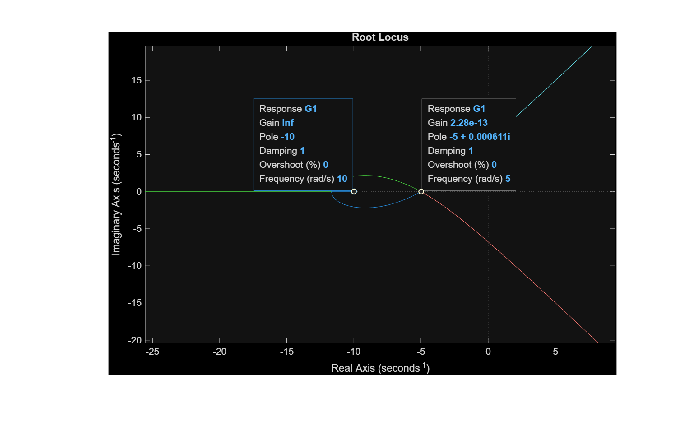

figure;
imshow('fig3_poloszeros.png');

**1.2 Quais são as raízes quando **$K=0$** e **$K\longrightarrow \infty$**?Explicitar as assíntotas quando houver. **

R: 

Para $K=0$, os polos de malha fechada estão localizados em $ $s = -5$$. À medida que $K\longrightarrow \infty$, um polo se desloca para o zero em $ $s = -10$$ e os outros três tendem ao infinito. Como há 3 polos indo para o infinito, eles seguem 3 assíntotas. O centroide dessas assíntotas no eixo real ocorre em $$\sigma_a = -3,33$$, projetando-se com ângulos de $$60^\circ$$, $$180^\circ$$ e $$-60^\circ$$. Além disso, a partir de um determinado valor crítico de ganho, os dois polos que seguem as assíntotas de $$\pm 60^\circ$$ cruzam o eixo imaginário em direção ao semiplano direito, tornando o sistema instável.

**1.3 Para que valores de **$K\in[-\infty, \infty ]$** esse sistema é estável? Obter a partir do LR e da expressão **$1+KG_1(s)=0$**, e não do critério de Routh Hurwitz.**

R: 

O sistema é estável para um intervalo específico de ganhos $$K$$, tanto positivos quanto negativos. Para encontrar esses limites, utilizamos a Função de Transferência (FT) da planta obtida através da análise da imagem: $$G_1(s)=\frac{(s+10)}{(s+5)^4}$$.

**Para **$$K > 0$$**:**

Pelo gráfico é possível identificar de forma aproximada a coordenada na qual as trajetórias cruzam o eixo imaginário. Isso ocorre em $$s=\pm j6,75$$. Quando substituímos esse valor em $$G_1(s)$$, obtemos $$G_1(j6,75) = 2.423 \times 10^{-3} \angle -179.87^\circ$$. Para encontrar o valor limite superior de K, utilizamos a condição de magnitude $$1 + KG_1(s) = 0 \Rightarrow K = \frac{1}{\vert{}G_1(j6,75)\vert{}} \Rightarrow K = 412,689$$. Portanto, para $$K > 412,689$$ o sistema torna-se instável.

**Para **$$K < 0$$**:**

Avaliando o lugar das raízes complementar (para ganhos negativos), a regra determina que o locus existe no eixo real à esquerda de um número par de polos e zeros. Como há zero elementos à direita de $$s = -5$$, o trecho de $$s = -5$$ até$$+\infty$$  faz parte do lugar das raízes. Isso indica que um polo caminha sobre o eixo real em direção ao semiplano direito e cruza o eixo imaginário exatamente na origem ($$s = 0$$).

Substituindo $$s = 0$$ na equação característica, temos:

$$1 + K \cdot G_1(0) = 0 \Rightarrow 1 + K \left[\frac{10}{5^4}\right] = 0 \Rightarrow 1 + K \left[\frac{10}{625}\right] = 0 \Rightarrow K = -62,5$$.

Portanto, para ganhos $$K < -62,5$$, o polo assume parte real positiva e o sistema torna-se instável.

**Conclusão:**

O sistema é estável apenas para a faixa de valores $$-62,5 < K < 412,689$$.

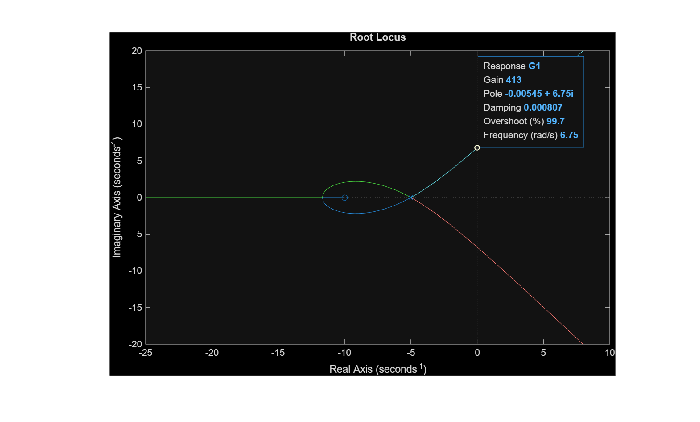

figure;
imshow('fig3_ganho.png');

**1.4 Para que valores de K o par de polos complexos dominante tem amortecimento **$\zeta\geq0.707$** (UP<4.3%)?**

R: 

Para um fator de amortecimento $\zeta\geq0.707$, a defasagem angular em relação ao semieixo real negativo é de $\zeta = 0.707 \rightarrow \arccos(\zeta) = \arccos(0.707) \rightarrow \theta = 45^\circ$. Analisando a imagem, a reta preta representa esse amortecimento constante e cruza a trajetória dos polos em, aproximadamente, $$s = -2,75 \pm j2,75$$. Com base nisso, podemos usar a mesma lógica da questão 1.3 e calcular primeiro o módulo da planta $$|G_1(-2,75 + j2,75)|$$. Em seguida, para encontrar o valor correspondente de $$K$$, utilizamos a condição de magnitude $$K = \frac{1}{|G_1(s)|}$$. Ou seja, para alocar os polos na posição aproximada de $$s = -2,75 \pm j2,75$$, teremos um ganho $$K \approx 20.5$$.

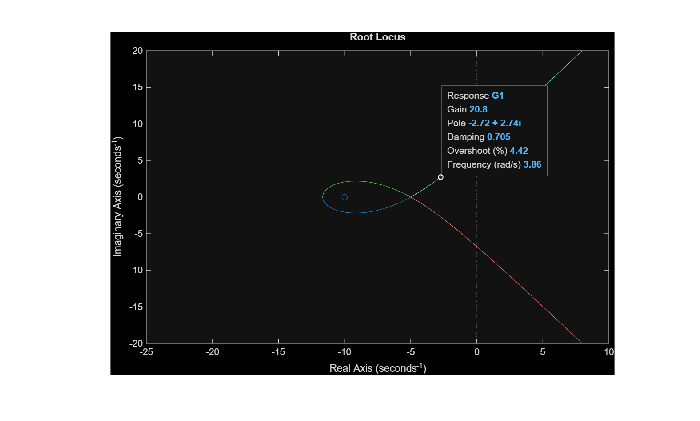

figure;
imshow('fig3_damping.png');

**1.5 Feche a malha de **$G_1 $**com este ganho, plote a resposta ao degrau, e veja se obteve a sobreelevação limitada a 4.3%. Caso não, explique.**

R: 

A partir da análise do gráfico de resposta ao degrau, observa-se que o sistema apresentou uma sobreelevação (overshoot) de **3,38%** para o ganho $$K = 20.5$$.

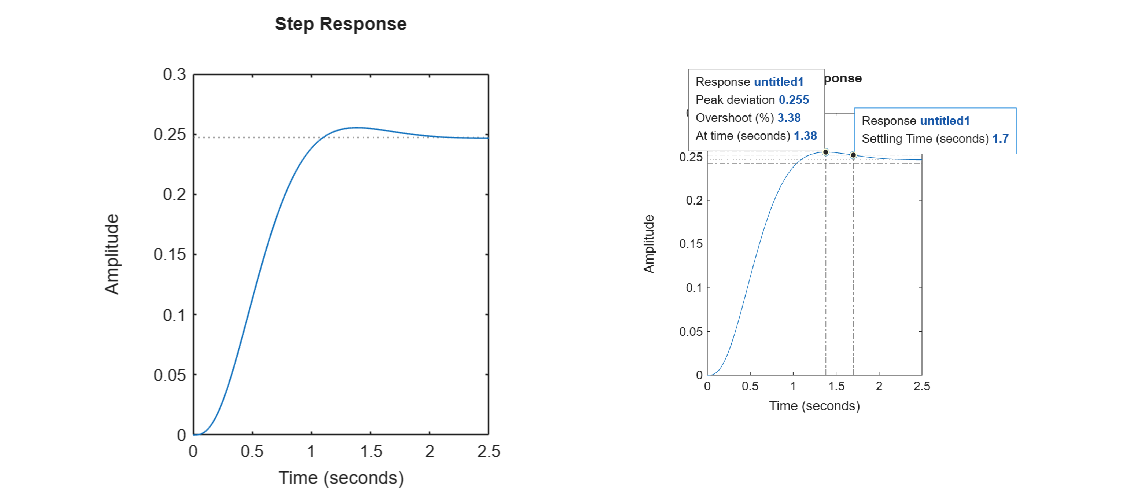

k1 = 20.5;
num = [1 10];
polos = poly([-5 -5 -5 -5]);
g1 = tf(num,polos);
figure('Position',[100, 100, 900, 400]);
subplot(1,2,1);
step(feedback(g1*k1,1))
subplot(1,2,2);
imshow('fig3_K.png');

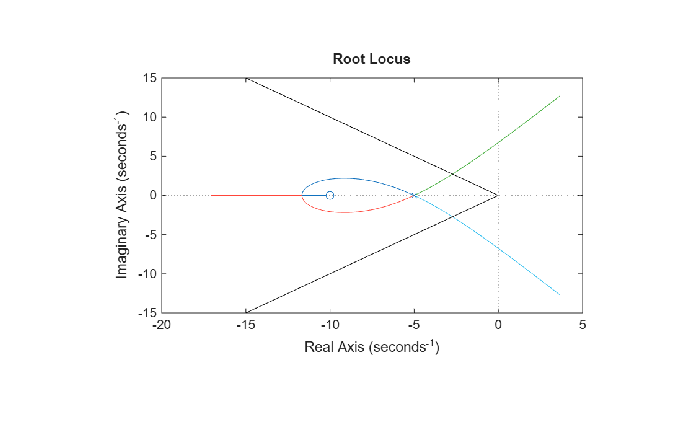

figure;
imshow('fig1.png');

**Atividade 2: A figura mostra o lugar das raízes de **$1+KG_2(s)=0$, **sendo **$G_2$** da forma **$G_2(s)=\frac{(s+z_1)(s+z_2)...}{(s+p_1)(s+p_2)...}$, **com as restrições de projeto em relação a sobreelevação e tempo de estabelecimento. Responder as perguntas abaixo:**

2.1 Para que valores de $K > 0$ este sistema é estável? Obter a partir do LR e da expressão $1+KG_2(s)=0$, e não do critério de Routh Hurwitz.

R:

Analisando o Lugar das Raízes (LR), podemos notar que o sistema possui dois polos ($ $P = 2$$) e nenhum zero ($$Z = 0$$). A quantidade de assíntotas é dada pela diferença entre o número de polos e zeros ($$P - Z$$), o que significa que teremos $$2$$ assíntotas.

Podemos calcular os ângulos dessas assíntotas através da equação:


$$$$\theta_{as} = \frac{(2r + 1)180^\circ}{P - Z}$$$$


sendo $$r = 0, 1, 2, \dots$$

Substituindo os valores na equação:

- Para $$r = 0$$, teremos $$\theta_{as} = 90^\circ$$.

- Para $$r = 1$$, teremos $$\theta_{as} = 270^\circ$ (ou $-90^\circ$)$.

Portanto, as duas assíntotas estarão posicionadas na vertical, indicando que um polo seguirá um caminho para cima e o outro para baixo.

Com base nisso, concluímos que, para valores de ganho $$K > 0$$, o sistema continuará sempre estável. Isso ocorre pois os polos se movem paralelamente ao eixo imaginário ($$j\omega$$) e nunca o cruzarão em direção ao semiplano direito. O efeito prático desse deslocamento vertical é a redução do fator de amortecimento ($$\zeta$$), o que causará o aumento da sobreelevação (overshoot) do sistema de forma proporcional ao aumento de $$K$$.

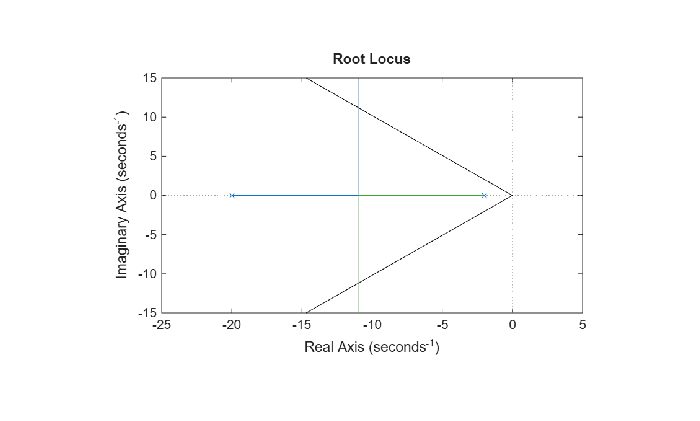

figure;
imshow('fig2.png');

2.2 Quais as especificações de UP e tempo de estabelecimento mostradas (aproximadamente)?

R:

A restrição de tempo de estabelecimento é representada pela linha vertical preta. Observando o eixo real, notamos que essa linha cruza exatamente a coordenada $$\sigma = -10$$. Para que o sistema atenda ao requisito de rapidez, os polos devem estar à esquerda dessa marca (ou seja, ter parte real com módulo $$\ge 10$$).

Utilizando o critério de $$2\%$$, o tempo de estabelecimento máximo permitido é:


$$$$t_s = \frac{4}{|\sigma|} \rightarrow t_s = \frac{4}{10} = 0,4 \text{ segundos}$$$$


A restrição de sobreelevação é representada pelas duas linhas diagonais pretas. Notamos que elas partem da origem $$(0,0)$$ e cruzam a marca de $$-10$$ no eixo real exatamente na altura de $$10$$ e $$-10$$ no eixo imaginário. Isso forma um triângulo retângulo com catetos iguais, o que indica um ângulo de $$\theta = 45^\circ$$ em relação ao eixo real negativo.

O fator de amortecimento ($$\zeta$$) correspondente a esse ângulo é:


$$$$\zeta = \cos(45^\circ) = \frac{\sqrt{2}}{2} \approx 0,707$$$$


Substituindo esse valor na equação da sobreelevação:


$$$$UP = 100 \cdot e^{-\frac{\pi\zeta}{\sqrt{1-\zeta^2}}}$$$$



$$$$UP = 100 \cdot e^{-\frac{\pi \cdot 0,707}{\sqrt{1 - 0,707^2}}} \approx 4,3\%$$$$


figure;
imshow('fig2.png');

2.3 Para que valores de K as especificações são atendidas? Plote a resposta ao degrau com este ganho confirmando.

R:

Para determinar a faixa do ganho $$K$$, precisamos encontrar a função de transferência de malha aberta do sistema, $$G(s)$$. Observando os marcadores no Lugar das Raízes, identificamos dois polos originais no eixo real em $$s = -2$ e $s = -20$$. Com isso, definimos a planta do sistema como $$G(s) = \frac{1}{(s+2)(s+20)} = \frac{1}{s^2 + 22s + 40}$$. Em seguida, aplicamos a condição de malha fechada $$1 + KG(s) = 0$$ para obter a equação característica, que resulta no polinômio $$s^2 + 22s + (40 + K) = 0$$.

A partir dessa equação, aplicamos os limites das especificações. A restrição de tempo de estabelecimento exige que a parte real dos polos seja, no máximo, $$-10$$. Substituindo $$s = -10$$ na equação característica, temos $$(-10)^2 + 22(-10) + 40 + K = 0$$, o que resulta no limite mínimo de $$K = 80$$. Por outro lado, a restrição de sobreelevação impõe que os polos não ultrapassem as retas diagonais de $$45^\circ$$. Como a trajetória dos polos sobe verticalmente a partir da parte real $$-11$$, o cruzamento com a diagonal ocorre exatamente em $$s = -11 \pm j11$$. Substituindo esse valor complexo diretamente na equação característica, temos $$(-11 + j11)^2 + 22(-11 + j11) + 40 + K = 0$$, que se simplifica algebricamente para $$-202 + K = 0$$, definindo o limite máximo de $$K = 202$$. Dessa forma, conclui-se objetivamente que ambas as especificações são garantidas simultaneamente para o intervalo de ganho $$80 \le K \le 202$$.

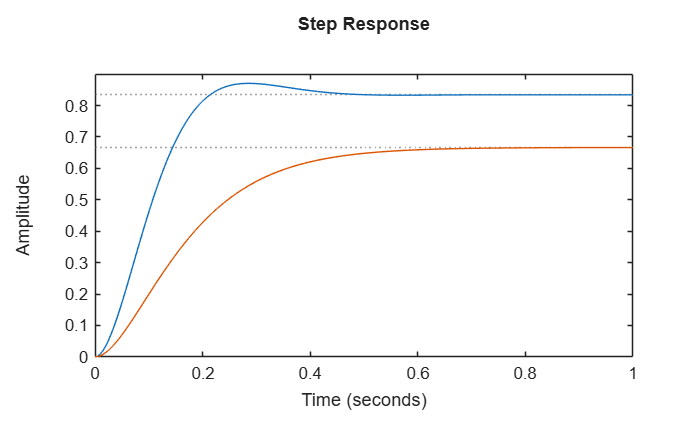

K_min = 80;
K_max = 202;
num2 = 1;
polos2 = [-2 -20];
den2 = poly(polos2);
G2 = tf(num2,den2);
MF_G2_Kmin = feedback(K_min*G2,1);
MF_G2_Kmax = feedback(K_max*G2,1);

figure;
step(MF_G2_Kmax);
hold on;
step(MF_G2_Kmin);
hold off;


stepinfo(MF_G2_Kmax)

ans = struct with fields:
         RiseTime: 0.1381
    TransientTime: 0.3833
     SettlingTime: 0.3833
      SettlingMin: 0.7541
      SettlingMax: 0.8708
        Overshoot: 4.3210
       Undershoot: 0
             Peak: 0.8708
         PeakTime: 0.2847


stepinfo(MF_G2_Kmin)

ans = struct with fields:
         RiseTime: 0.3085
    TransientTime: 0.5369
     SettlingTime: 0.5369
      SettlingMin: 0.6013
      SettlingMax: 0.6666
        Overshoot: 0
       Undershoot: 0
             Peak: 0.6666
         PeakTime: 1.1006


2.4 Faça o LR para $G_2(z)$ com Ts dado (g2ts), e obtenha dele os valores de K que atendem as mesmas especificações no plano z. Plote a resposta ao degrau com este ganho confirmando.

R:

Para realizar o projeto no domínio discreto, primeiramente a planta contínua $$G_2(s)$$ foi discretizada para $G_2(z)$ utilizando a função c2d em conjunto com o tempo de amostragem fornecido de $$T_s = 0,016$$ s.  

No plano Z, as especificações de projeto sofrem um mapeamento diferente do plano S, guiado pela relação matemática $$z = e^{sT_s}$$:

- **Tempo de Estabelecimento (**$$t_s \le 0,4$ $**s):** No plano S, isso exigia que a parte real dos polos fosse $$\sigma \le -10$$. No plano Z, essa restrição mapeia para um círculo de raio constante dado por $$r = e^{\sigma T_s} = e^{-10 \times 0,016} \approx 0,852$$. Para atender à rapidez, os polos devem operar dentro desse limite.  

- **Sobreelevação (**$$UP \le 4,3\%$$** ou **$$\zeta \ge 0,707$$**):** No plano S, a restrição de amortecimento constante formava retas diagonais. No plano Z, essas linhas de $$\zeta$$ constante se transformam em espirais logarítmicas.  

Analisando o Lugar das Raízes discreto gerado, busquei um ganho $$K$$ que alocasse os polos de malha fechada na intersecção dessas duas regiões válidas. Através dos marcadores no gráfico, identificamos que um ganho $$K = 154$$ posiciona os polos em $$z = 0,839 \pm j0,125$$. Nessa localização, o sistema possui um fator de amortecimento de $$\zeta = 0,745$,$ resultando em uma sobreelevação teórica de aproximadamente 3%. Isso atende perfeitamente ao requisito limitante de $$UP \le 4,3\%$$.  

O gráfico da resposta ao degrau aplicando esse ganho $$K = 154$$ confirmou o projeto, mostrando um sobressinal de 3,05% e um tempo de estabelecimento de 0,432 s (que está próximo do limite prático quando discretizado). Apenas como verificação do limite superior, testar um ganho maior como $$K = 175,2$$ já resulta em um *overshoot* de 4,61%, violando as exigências de projeto.

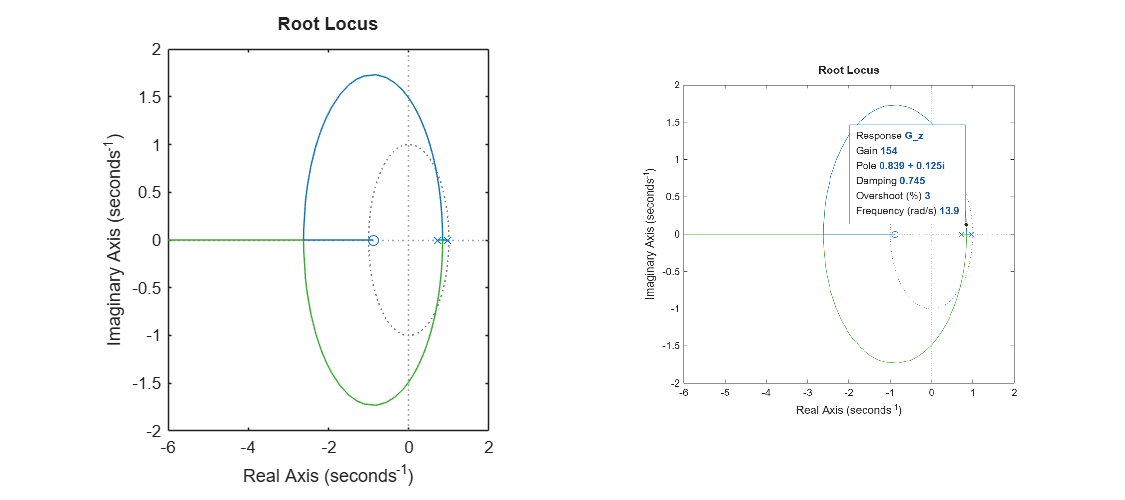

G_z = c2d(G2,g2ts);
figure('Position', [100, 100, 900, 400]);
subplot(1,2,1);
rlocus(G_z);
subplot(1,2,2);
imshow('fig4_lrdiscreto.png');

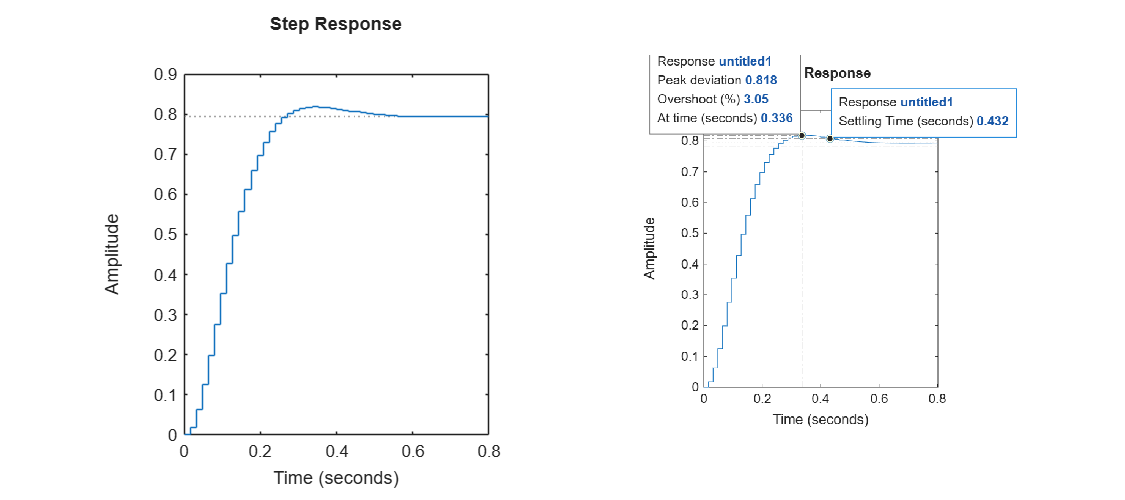

figure('Position', [100, 100, 900, 400]);
subplot(1,2,1);
step(feedback(G_z*154,1));
subplot(1,2,2);
imshow('fig4_resp.png')

stepinfo(feedback(G_z*175.2,1))

ans = struct with fields:
         RiseTime: 0.1440
    TransientTime: 0.4160
     SettlingTime: 0.4160
      SettlingMin: 0.7607
      SettlingMax: 0.8517
        Overshoot: 4.6148
       Undershoot: 0
             Peak: 0.8517
         PeakTime: 0.3040


**Atividade 3: Seja o lugar das raízes mostrado para Kp com Kd=0 para **$1+K_p(s+\frac{Kd}{K_p})G_3(s)=0$**. **

3.1 Explique o efeito da adição do zero em $s=-\frac{K_d}{K_p}$ em diferentes localizações do eixo real sobre este LR, explicando que efeito haverá na resposta ao degrau. Use as propriedades do método do LR para explicar e justificar.

g3;

R:

Na primeira linha onde mostra o LR e a resposta ao degrau, o zero foi colocado perto da origem. Pela regra dos ramos no LR, um polo de malha fechada será atraído para perto da origem. Como a estabilidade e a velocidade dependem da distância do eixo imaginário, esse polo se torna o polo dominante da resposta.  Com base nisso o polo dominante está muito perto da origem (parte real pequena), a resposta é muito lenta (tempo de estabelecimento alto). Além disso, como o zero está muito próximo do eixo, o efeito antecipatório (ação derivativa) atua com força máxima sobre o degrau, gerando um sobressinal alto.

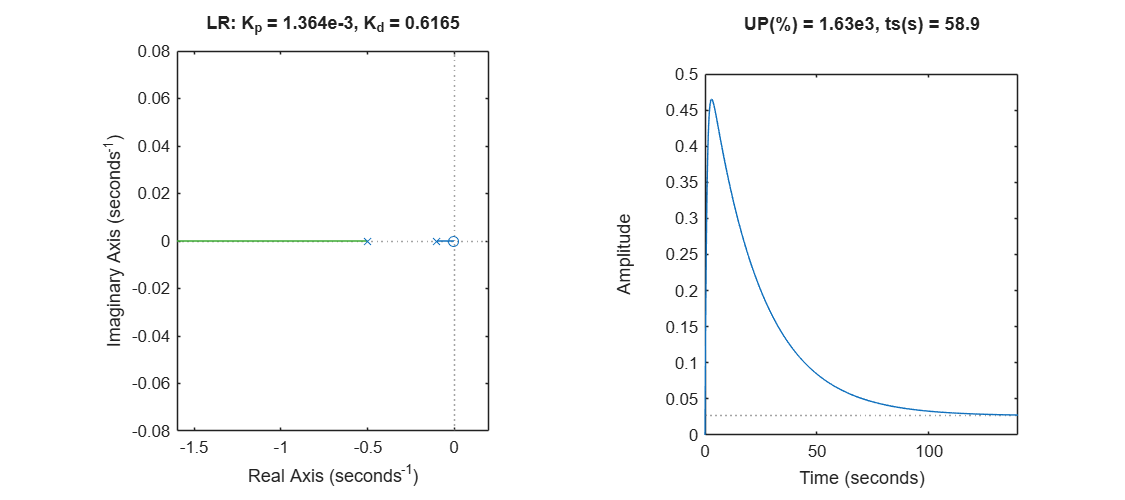

Malha_aberta = C*G;
figure('Position', [100, 100, 900, 400]);
subplot(1,2,1);
rlocus(Malha_aberta);
title('LR: K_p = 1.364e-3, K_d = 0.6165');
subplot(1,2,2);
step(feedback(Malha_aberta,1));
title('UP(%) = 1.63e3, ts(s) = 58.9');

Na segunda linha, o zero foi posicionado entre os dois polos no eixo real. De acordo com a regra dos segmentos no eixo real do LR, isso faz com que um polo caminhe em direção ao zero e o outro caminhe para o infinito negativo. Consequentemente, não há ponto de descolamento e os ramos nunca saem do eixo real, garantindo que os polos de malha fechada sejam estritamente reais para qualquer ganho. Como não há polos complexos, o sistema nunca será subamortecido, o que justifica a ausência de sobressinal (UP = 0).  Além disso, o polo que vai para o infinito perde influência, fazendo o sistema se comportar como um modelo de primeira ordem dominado pelo polo restante, que agora está mais à esquerda, o que garante um tempo de estabelecimento muito melhor do que no caso anterior.

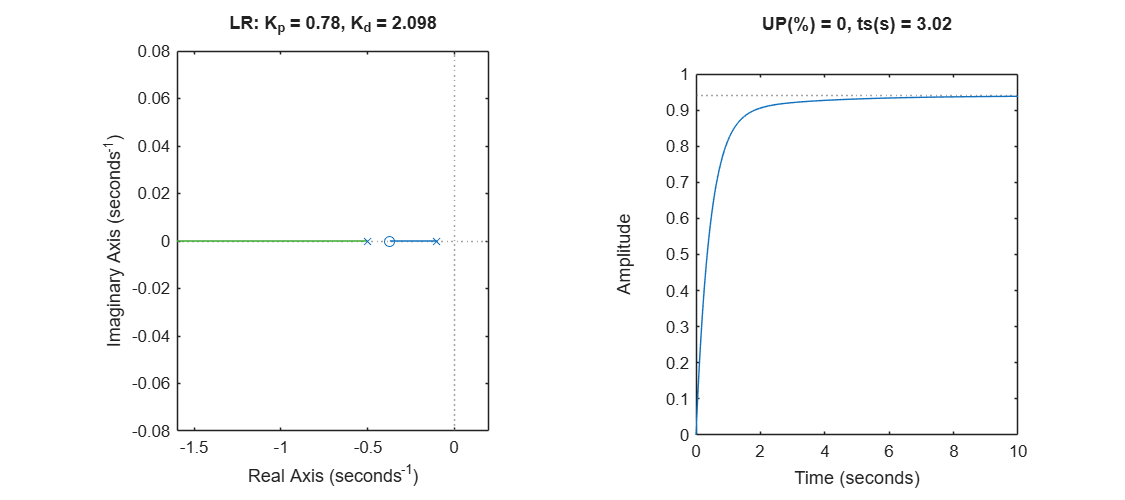

Malha_aberta1 = C_1*G_1;
figure('Position', [100, 100, 900, 400]);
subplot(1,2,1);
rlocus(Malha_aberta1);
title('LR: K_p = 0.78, K_d = 2.098');
subplot(1,2,2);
step(feedback(Malha_aberta1,1));
title('UP(%) = 0, ts(s) = 3.02');

Na terceira linha, o zero foi alocado à esquerda dos dois polos. De acordo com as propriedades do LR, há um trecho válido entre os dois polos no eixo real, o que gera um ponto de descolamento. Isso faz com que, em um dado intervalo de valores de ganho K, os polos saiam do eixo real e se tornem complexos conjugados, formando uma trajetória circular devido à atração do zero. A presença da parte imaginária nesses polos torna o sistema subamortecido, o que justifica o aparecimento do sobressinal na resposta ao degrau. Além disso, como o zero puxa o lugar das raízes mais para a esquerda (aumentando a parte real negativa dos polos), o sistema fica mais rápido, resultando em um tempo de estabelecimento consideravelmente menor.

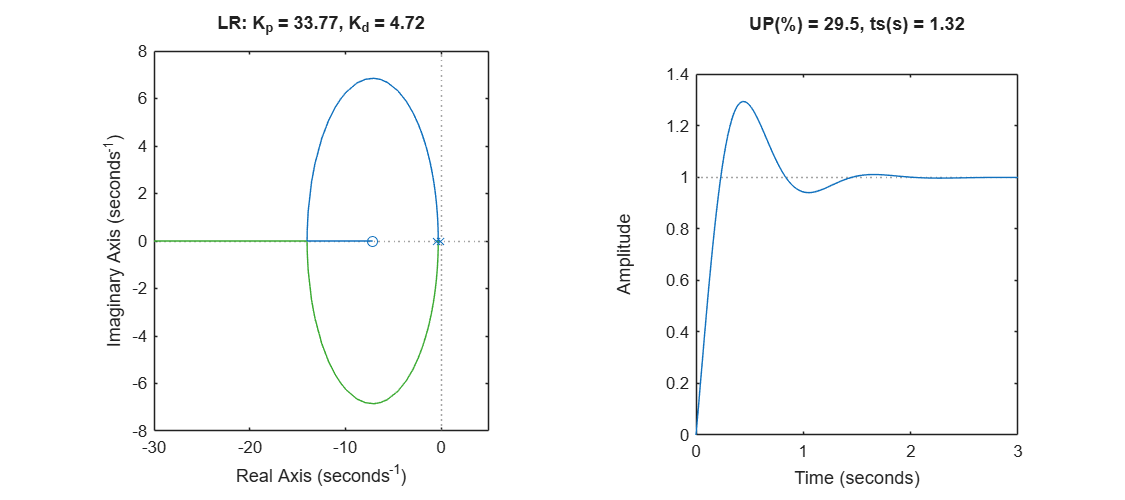

Malha_aberta2 = C_2*G_2;
figure('Position', [100, 100, 900, 400]);
subplot(1,2,1);
rlocus(Malha_aberta2);
title('LR: K_p = 33.77, K_d = 4.72');
subplot(1,2,2);
step(feedback(Malha_aberta2,1));
title('UP(%) = 29.5, ts(s) = 1.32');

3.2 Projete um controlador PD que forneça a resposta mostrada abaixo. Explique como fez o projeto, forneça os ganhos Kp e Kd e plote no mesmo gráfico a resposta desejada e a que foi obtida.

R:

*Primeiramente, analisei a curva de referência e extraí os requisitos de desempenho desejados: um sobressinal de aproximadamente **19%** e um tempo de estabelecimento  de **2.993**s. A presença de sobressinal indica que o sistema em malha fechada precisa ser dominado por polos complexos conjugados.*

*Para obter esse comportamento, projetei um controlador PD inserindo a planta no **rltool**. Adicionei um zero à esquerda dos polos de malha aberta. Como justificado anteriormente, esse zero atrai o lugar das raízes, forçando o descolamento dos ramos do eixo real para o plano complexo.*

*Em seguida, ajustei a posição desse zero e o ganho do sistema até que os polos de malha fechada cruzassem a região do plano-**s** que atende aos requisitos de amortecimento e velocidade da referência.*

*A função do controlador obtida foi **C(s) = 2.065(s + 2.533)**. Expandindo para o formato padrão do PD (**C(s) = K_p + K_d s**), os ganhos finais do projeto são:*

- **K_p = 5.231**

- **K_d = 2.065**

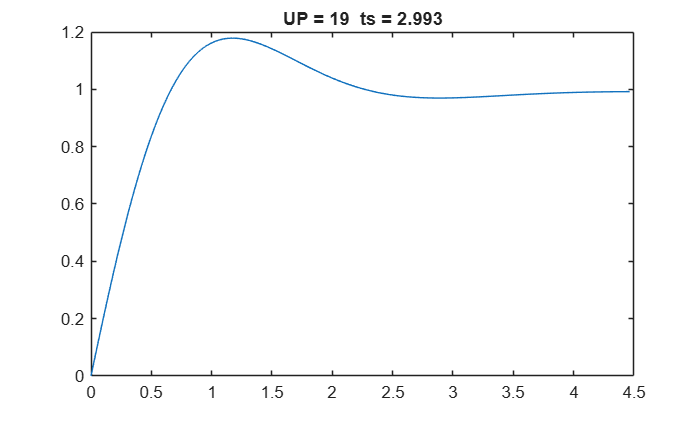

figure;
plot(g3ref.t,g3ref.y),title(g3ref.ss);

Malha_aberta3 = C_3*G_3;
Malha_fechada = feedback(Malha_aberta3,1);
[y,~] = step(Malha_fechada,g3ref.t);

stepinfo(Malha_fechada)

ans = struct with fields:
         RiseTime: 0.4855
    TransientTime: 2.9158
     SettlingTime: 2.9158
      SettlingMin: 0.9124
      SettlingMax: 1.1800
        Overshoot: 19.1312
       Undershoot: 0
             Peak: 1.1800
         PeakTime: 1.1405


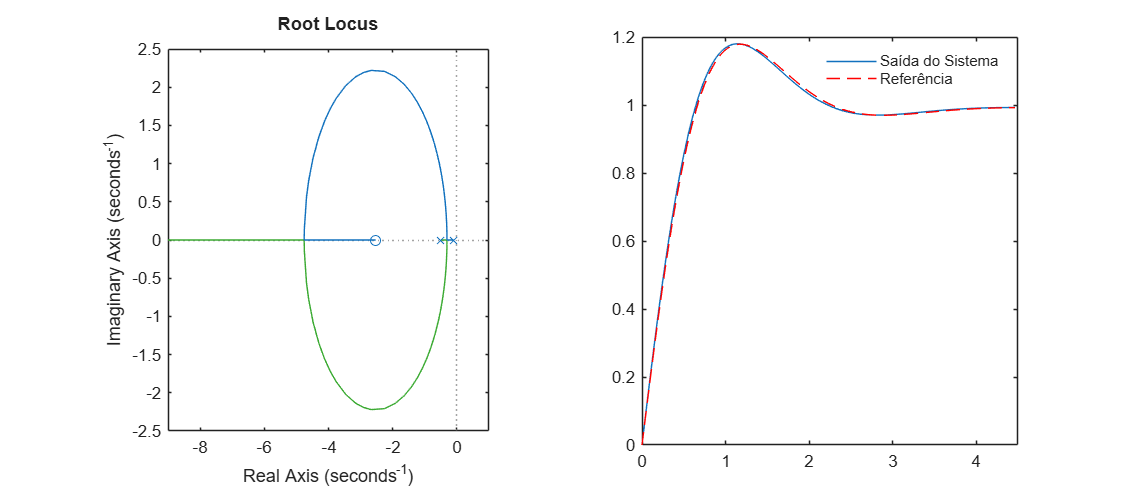

figure('Position', [100, 100, 900, 400]);
subplot(1,2,1);
rlocus(Malha_aberta3);
subplot(1,2,2);
plot(g3ref.t,y);
hold on;
plot(g3ref.t,g3ref.y,'r--');
hold off;
xlim([0,4.5]);
legend('Saída do Sistema', 'Referência');
legend boxoff;

**Atividade 4: **Seja a função de transferência dada $G_4(s)$ e a resposta dada por um modelo de referência mostrada. Use  o método do lugar das raízes para projetar um controlador PI, avaliando o efeito da localização do zero para conseguir um desempenho igual ou melhor que o modelo de referência. O desempenho deve ser medido pelo IAE, usando uma janela de tempo de mesma duração na figura mostrada. **IMPORTANTE**: plote a resposta obtida junto com a resposta do modelo de referência g4perf.y na mesma figura. Lembrando: IAE=trapz(t,abs(1-y));

R:

Para o projeto do controlador PI pelo método do Lugar das Raízes, é preciso analisar o impacto da adição de um polo na origem ($$s=0$$) e de um zero ($$z_c$$). O polo integrador é essencial para garantir erro nulo em regime permanente, mas tem o efeito colateral de atrair os ramos do LR para o semiplano direito, reduzindo a estabilidade relativa do sistema. Para compensar isso, utilizamos o zero do controlador.

**Avaliação da localização do zero (**$$z_c$$**):**

O posicionamento deste zero define o compromisso entre a rapidez da resposta e a estabilidade, o que é especialmente crítico em uma planta com um atraso de transporte severo ($$e^{-7s}$$), como é o caso de $$G_4(s)$$.

- Se o zero for alocado muito próximo à origem, ele praticamente cancela o efeito do polo integrador. A resposta fica excessivamente lenta, o que aumentaria drasticamente o valor do IAE e o tempo de estabelecimento.

- Se o zero for afastado muito para a esquerda, ele atrai os ramos do LR para regiões de maior amortecimento. Contudo, tentar forçar um sistema com grande tempo morto a ser muito rápido faz com que o atraso de fase empurre os polos fechados para o semiplano direito, gerando uma sobreelevação (*overshoot*) excessiva ou até mesmo instabilidade.

**Sintonia e Desempenho:**Através da sintonia pelo Lugar das Raízes, o melhor ponto de operação encontrado posiciona o zero em $$s \approx -0,0691$$, resultando nos ganhos finais de $$K_p = 0,032478$$ e $$K_i = 0,0022465$$.  

A sobreposição das respostas ao degrau demonstra que o sistema em malha fechada acompanhou fielmente a dinâmica do modelo de referência, respeitando o tempo morto inicial de aproximadamente 7 segundos. O índice de erro absoluto integral obtido foi $$IAE = 14,5655$$, um valor bastante competitivo e próximo à métrica do modelo de referência ($$IAE = 14,2368$$), comprovando que o controlador atingiu um desempenho equivalente, mantendo a sobreelevação controlada e o tempo de estabelecimento alinhado aos requisitos.

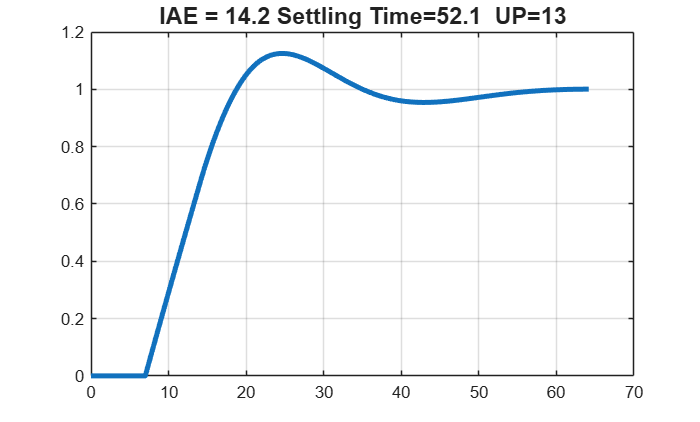

g4;
figure;
plot(g4ref.t,g4ref.y,'LineWidth',3);grid;
title(g4ref.ss,'FontSize',14);

Kp = 0.032478;
Ki = 2.24650326e-3;
C_PI = tf([Kp Ki],[1 0]);
Malha_aberta_GPI = C_PI * g4;
Malha_Fechada_GPI = feedback(Malha_aberta_GPI, 1);
[y, t] = step(Malha_Fechada_GPI, g4ref.t);

IAE=trapz(t,abs(1-y));
disp(['O valor do IAE obtido foi: ', num2str(IAE)]);

O valor do IAE obtido foi: 14.5655


IAE_ref=trapz(t,abs(1-g4ref.y));
disp(['O valor do IAE referencia obtido foi: ', num2str(IAE_ref)]);

O valor do IAE referencia obtido foi: 14.2368


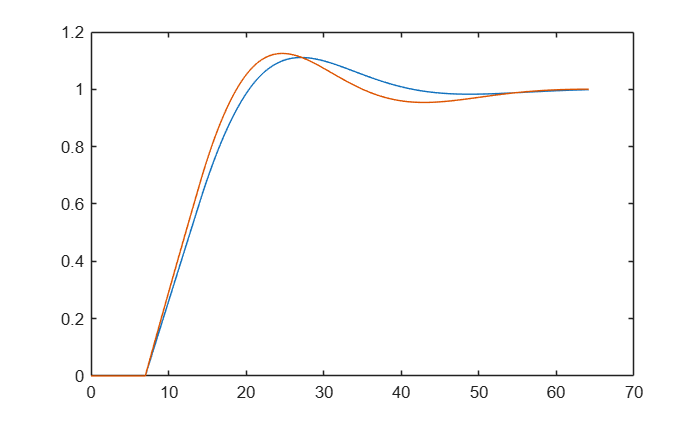

figure;
plot(t,y);
hold on;
plot(t,g4ref.y);

**Atividade 5: **Adicione um ganho derivativo ao controlador PI da atividade 4, de modo a reduzir a sobreelevação pela metade mantendo o mesmo tempo de estabelecimento obtido com o PI, explicando como projetou este controlador.

R:

Para adicionar a ação derivativa e transformar o controlador PI em um PID, foi necessário introduzir um segundo zero real na função de transferência do controlador através do rltool. Teoricamente, a adição de um zero aumenta o amortecimento do sistema, puxando o Lugar das Raízes mais para a esquerda, o que tem o efeito direto de frear a resposta e reduzir o sobressinal. O projeto foi realizado através de um ajuste iterativo de sintonia fina da posição desse novo zero e do ganho global do sistema. Como estratégia para manter o tempo de estabelecimento ($$t_s \approx 52$$s), o ganho foi ajustado de forma que os polos dominantes de malha fechada mantivessem aproximadamente a mesma parte real que possuíam no projeto do PI anterior. Simultaneamente, para reduzir a sobreelevação pela metade ($$UP \approx 6.5\%$), a posição do segundo zero foi afastada para a esquerda no eixo real. Isso calibrou a influência da ação derivativa, diminuindo a parte imaginária dos polos dominantes e aumentando o fator de amortecimento até que o pico da resposta atingisse o valor de projeto desejado.

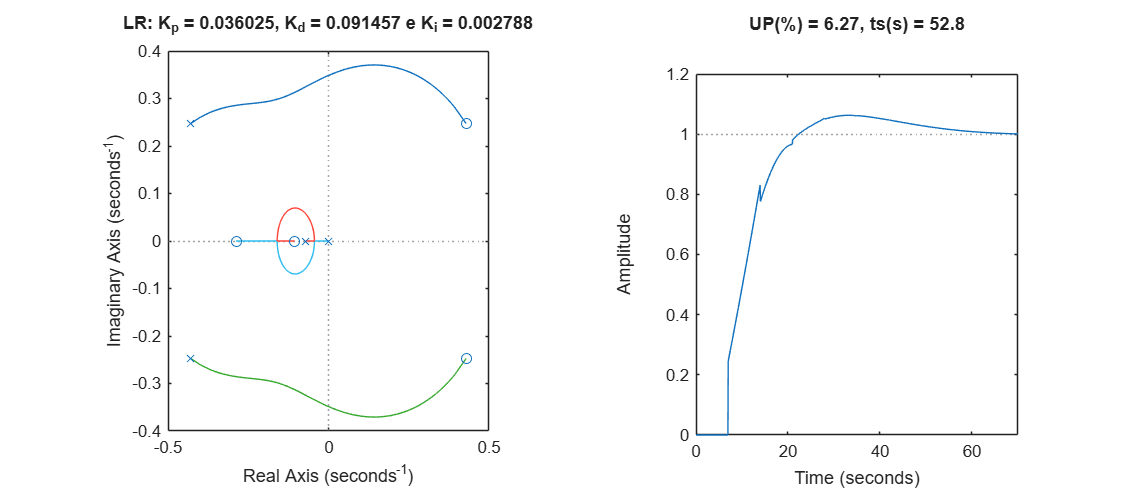

Malha_aberta_PID = C_4 * G_4;

G_4_pade = pade(G_4, 2); % O rlocus não estava deixando plotar sem usar Padé
Malha_aberta_PID_pade = C_4 * G_4_pade;

figure('Position', [100, 100, 900, 400]);

subplot(1,2,1);
rlocus(Malha_aberta_PID_pade);
title('LR: K_p = 0.036025, K_d = 0.091457 e K_i = 0.002788');

subplot(1,2,2);
step(feedback(Malha_aberta_PID, 1));
title('UP(%) = 6.27, ts(s) = 52.8');

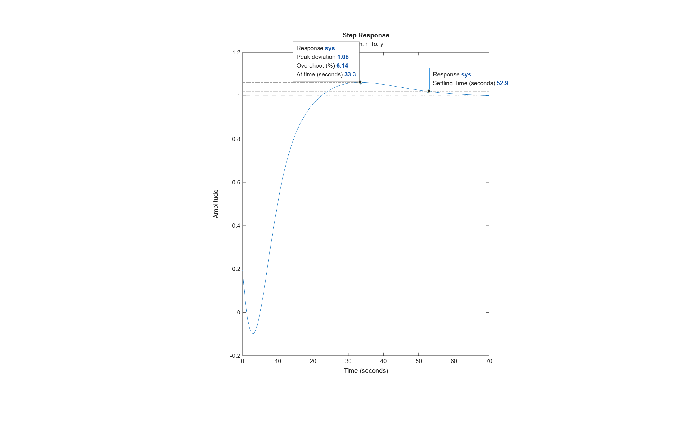

figure;
imshow('fig_5.png');

A figura acima mostra a resposta do sistema em malha fechada. As diferenças entre as duas imagens acima é por causa da aproximação de Padé. 